## SIOC 221A HW 6

## Kevin Okun

### Problem 1

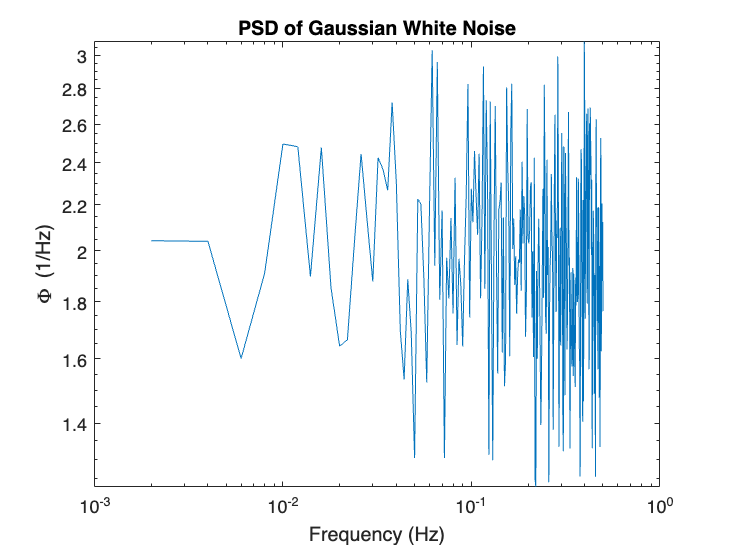

clear; close all;

% Create datasets
dt = 1; % units of seconds
data = randn(10000,1); % White noise, units O(1)
data_integral = cumsum(data)*dt; % Integral of white noise, units O(seconds)

% Segment data
data_segments = [reshape(data,500,20) reshape(data(251:9750),500,19)];
data_integral_segments = [reshape(data_integral,500,20) reshape(data_integral(251:9750),500,19)];

% Remove mean from each column before averaging
data_segments_removed = data_segments - mean(data_segments,1);
data_integral_segments_removed = data_integral_segments - mean(data_integral_segments,1);

% Average data
data_averaged = mean(data_segments_removed,2);
data_integral_averaged = mean(data_integral_segments_removed,2);

% FFT of data
data_fft = fft(data_segments_removed);
data_integral_fft = fft(data_integral_segments_removed);

% Compute spectral coefficients and frequency vector
data_spectra = abs(data_fft(1:length(data_fft)/2+1,:)).^2;
data_integral_spectra = abs(data_integral_fft(1:length(data_integral_fft)/2+1,:)).^2;

T = dt*length(data_fft); % Length of time series in seconds
df = 1/T; % Fundamental frequency
fn = 1/(2*dt); % Nyquist frequency
f=(0:df:fn)'; % Frequency vector

% Normalize spectra
data_spectra = data_spectra/(length(data_fft)).^2; % MATLAB normalization
data_integral_spectra = data_integral_spectra/(length(data_integral_fft)).^2;

data_spectra = data_spectra*2; % Half spectra
data_integral_spectra = data_integral_spectra*2;

data_spectra = data_spectra/df; % Units
data_integral_spectra = data_integral_spectra/df;

% Average data
data_spectra = mean(data_spectra,2);
data_integral_spectra = mean(data_integral_spectra,2);

figure(101)
loglog(f,mean(data_spectra,2))
title('PSD of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')

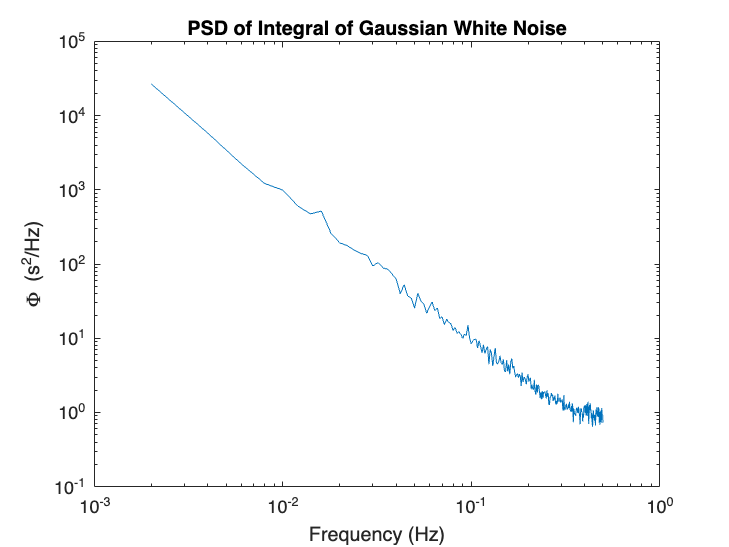


figure(102)
loglog(f,data_integral_spectra)
title('PSD of Integral of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (s^2/Hz)')


% Check variance
variance_data=mean(data_averaged.^2)

variance_data = 0.0243

sum_spectra = sum(data_spectra)*df

sum_spectra = 1.0045

sum_spectra / variance_data

ans = 41.3615


variance_data_integral = mean(data_integral_averaged.^2)

variance_data_integral = 0.7872

sum_spectra_integral = sum(data_integral_spectra)*df

sum_spectra_integral = 82.4013

sum_spectra_integral / variance_data_integral

ans = 104.6760

#### Problem 2

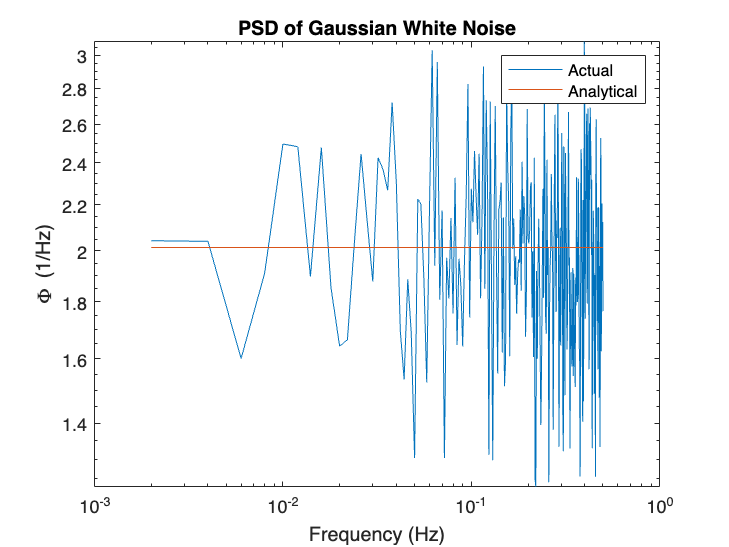

% From lecture, phi_N = sigma^2/fn
% Computing integral in fft space is same as dividing by 2pi*f^2

variance_data = mean(data.^2);
data_phi = variance_data/fn;
data_integral_phi = data_phi./((2*pi*f).^2);

figure(103)
loglog(f,data_spectra,f,data_phi*ones(251,1))
title('PSD of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Actual', 'Analytical')

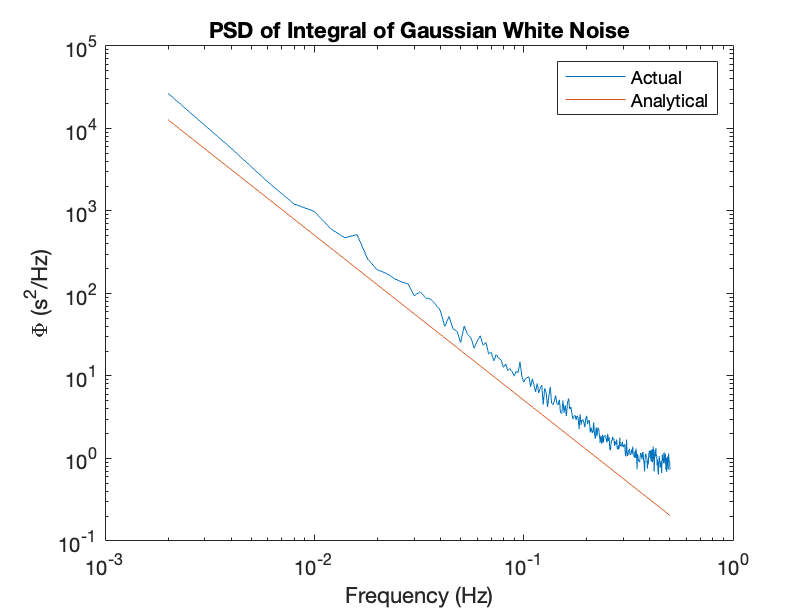


figure(104)
loglog(f,data_integral_spectra,f,data_integral_phi.*ones(251,1))
title('PSD of Integral of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (s^2/Hz)')
legend('Actual', 'Analytical')

#### Problem 3

% Add error bars to spectra
% Degrees of freedom for boxcar is 2*num_segments
nu = 2*39;
err_low = nu/chi2inv(1-.05/2,nu)

err_low = 0.7477

err_high = nu/chi2inv(.05/2,nu)

err_high = 1.4063

err_high/err_low

ans = 1.8807

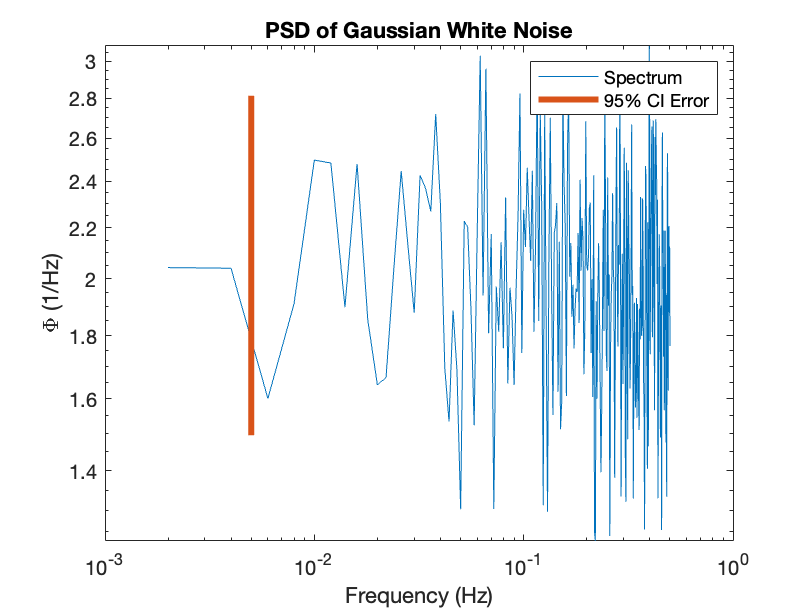


figure(105)
loglog(f,data_spectra)
hold on
semilogy([0.005 0.005],[err_low err_high].*2,LineWidth=3);
title('PSD of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Spectrum','95% CI Error')

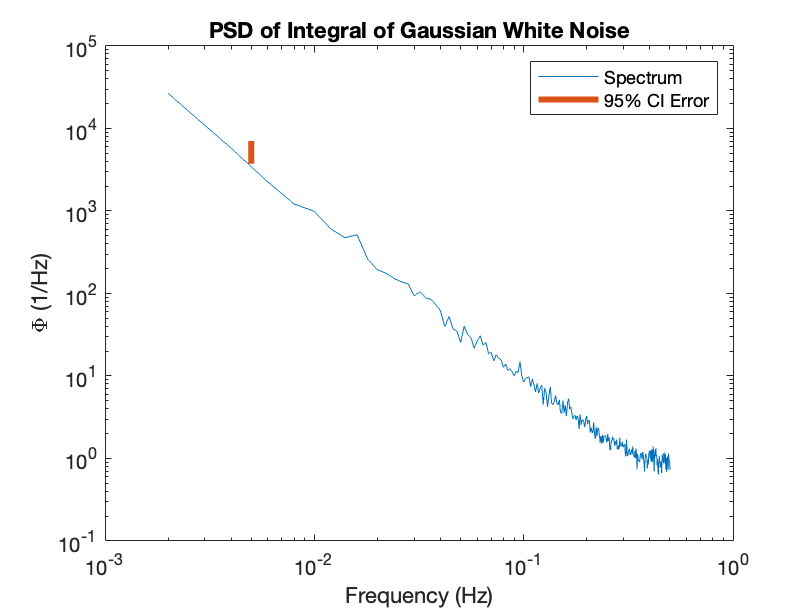


figure(106)
loglog(f,data_integral_spectra)
hold on
semilogy([0.005 0.005],[err_low err_high].*5*10^3,LineWidth=3);
title('PSD of Integral of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Spectrum','95% CI Error')

#### Problem 4

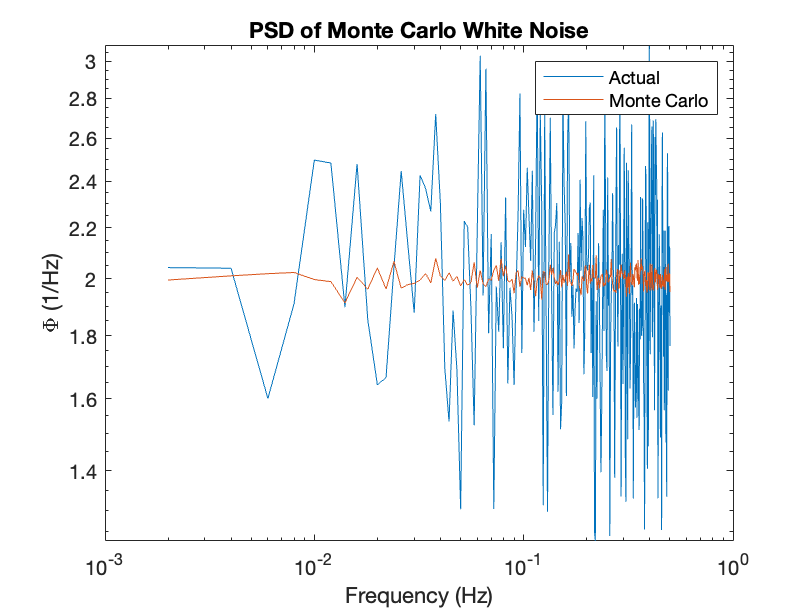

N1=500; %number of samples in each ensemble
N2=20;
Nb=200; %number of ensembles

A=randn(N1,N2,Nb); %Make 1000 realizations of fake data
mu=mean(A); %Compute the mean of each.
sigma_A=std(A); %And the standard deviation.  We expect this to be about one.

% Remove mean and calculate fft
A = A-mu;

A_fft = fft(A);
A_coef = abs(A_fft(1:length(A_fft)/2+1,:,:)).^2;

% Normalize
A_spectra = A_coef/(length(A_fft)).^2; % MATLAB normalization
A_spectra = A_spectra*2; % Half spectra
A_spectra = A_spectra/df; % Units

% Combine into one large ensemble
A_spectra_large = reshape(A_spectra,[251,4000]);

% Plot average spectra
figure(107)
loglog(f,data_spectra)
hold on
loglog(f,mean(A_spectra_large,2))
title('PSD of Monte Carlo White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Actual', 'Monte Carlo')

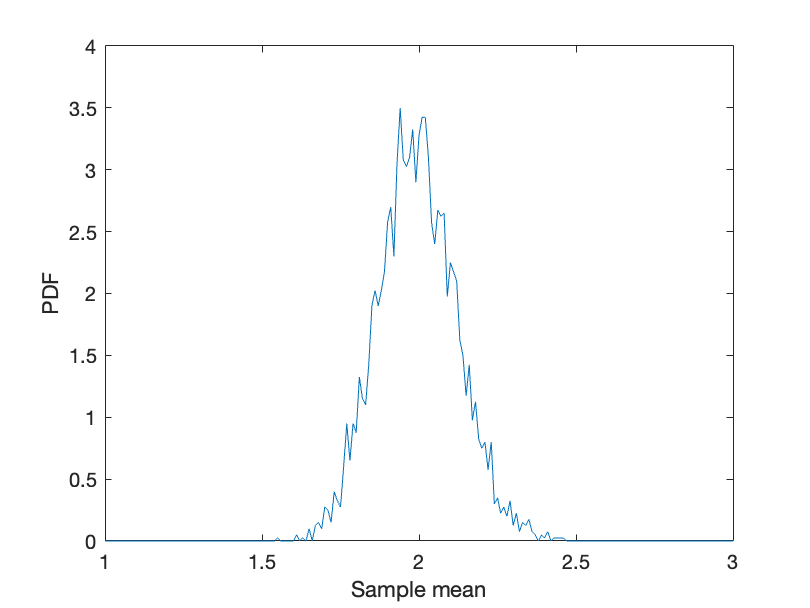


% Plot pdf
A_mu=mean(A_spectra_large,1);
A_sigma=std(A_spectra_large);
A_std=A_sigma/sqrt(500);
dx=0.01;
x=1:dx:3;
[h,v]=hist(A_mu,x);
h=h./sum(h)./dx;

figure(108)
plot(x,h)
ylabel('PDF')
xlabel('Sample mean')

At first glance, this looks like a gaussian. For a chi-squared variable with 100's of degrees of freedom, however, this is what I would expect the shape to look like.

% Sort each value at every frequency to determine error

% Average each 251x20 ensemble so we have 251 points and 200 ensembles
A_spectra_average = mean(A_spectra,2);
A_spectra_average = reshape(A_spectra_average,[251,200]);

A_spectra_sorted = NaN*ones(251,200);
A_error_low = NaN*ones(251,1);
A_error_high = A_error_low;
for idx = 1:251
    A_spectra_sorted(idx,:) = sort(A_spectra_average(idx,:));
    A_error_low(idx) = A_spectra_sorted(idx,6);
    A_error_high(idx) = A_spectra_sorted(idx,195);
end

mean(A_error_low)/2

ans = 0.6157

mean(A_error_high)/2

ans = 1.4640

mean(A_error_high)/mean(A_error_low)

ans = 2.3779

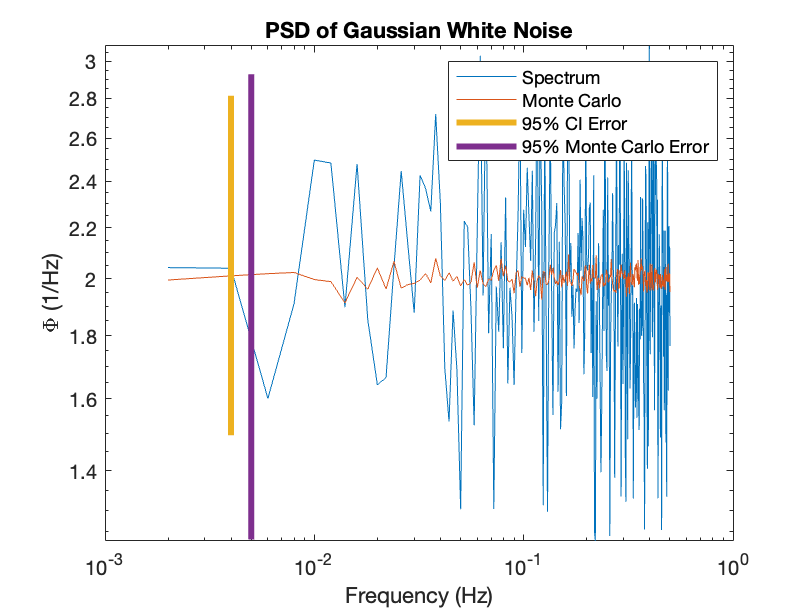


figure(109)
loglog(f,data_spectra)
hold on
loglog(f,mean(A_spectra_large,2))
semilogy([0.004 0.004],[err_low err_high].*2,LineWidth=3);
semilogy([0.005 0.005],[mean(A_error_low) mean(A_error_high)].*1,LineWidth=3);
title('PSD of Gaussian White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Spectrum','Monte Carlo','95% CI Error','95% Monte Carlo Error')

My error bars using the Monte Carlo method are slightly higher than the error bars above, but the ratio is very close. The spread in the spectrum is high, so the effective error in the Monte Carlo estimate is lower.

#### Problem 5

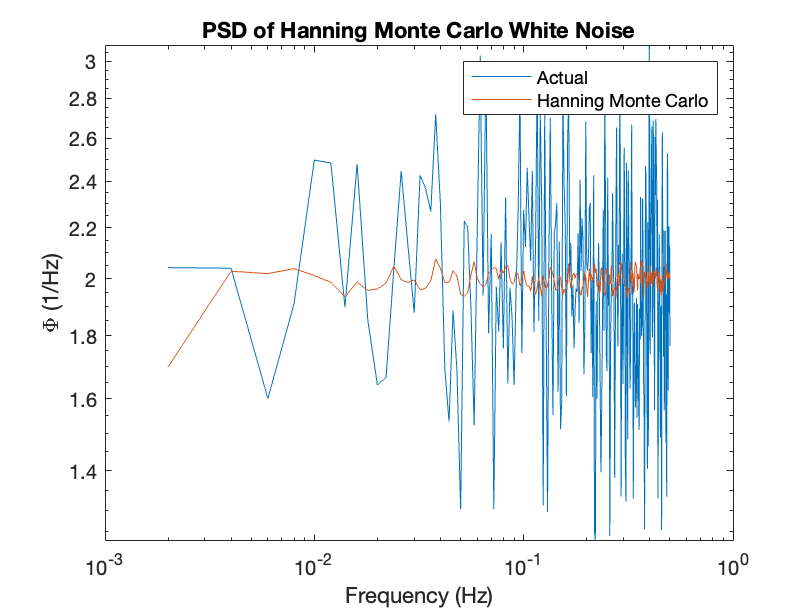

% Repeat with Hanning window
hann_window = sqrt(8/3)*hann(500);
A_hann = A.*hann_window;

A_hann_fft = fft(A_hann);
A_hann_coef = abs(A_hann_fft(1:length(A_hann_fft)/2+1,:,:)).^2;

% Normalize
A_hann_spectra = A_hann_coef/(length(A_hann_fft)).^2; % MATLAB normalization
A_hann_spectra = A_hann_spectra*2; % Half spectra
A_hann_spectra = A_hann_spectra/df; % Units

% Combine into one large ensemble
A_hann_spectra_large = reshape(A_hann_spectra,[251,4000]);

% Plot average spectra
figure(110)
loglog(f,data_spectra)
hold on
loglog(f,mean(A_hann_spectra_large,2))
title('PSD of Hanning Monte Carlo White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Actual', 'Hanning Monte Carlo')

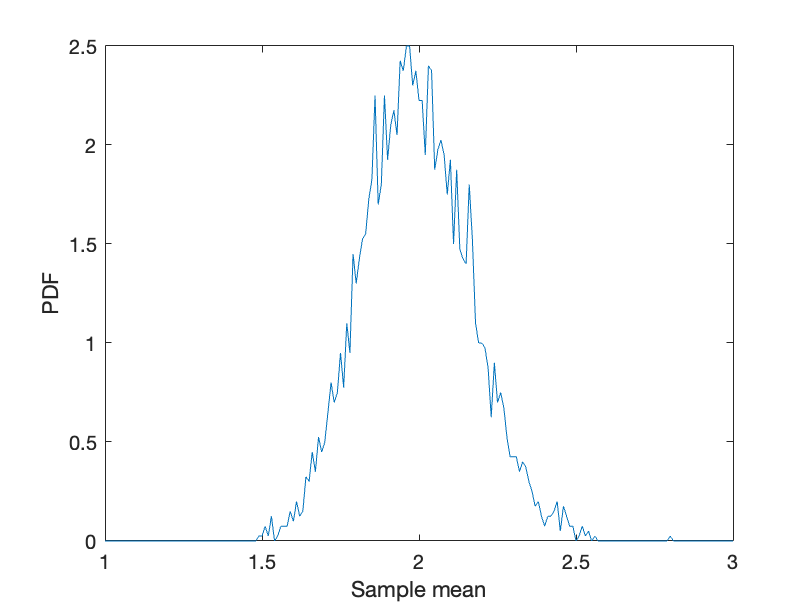


% Plot pdf
A_hann_mu=mean(A_hann_spectra_large,1);
A_hann_sigma=std(A_hann_spectra_large);
A_hann_std=A_hann_sigma/sqrt(500);
dx=0.01;
x=1:dx:3;
[h,v]=hist(A_hann_mu,x);
h=h./sum(h)./dx;

figure(111)
plot(x,h)
ylabel('PDF')
xlabel('Sample mean')


% Sort each value at every frequency to determine error

% Average each 251x20 ensemble so we have 251 points and 200 ensembles
A_hann_spectra_average = mean(A_hann_spectra,2);
A_hann_spectra_average = reshape(A_hann_spectra_average,[251,200]);

A_hann_spectra_sorted = NaN*ones(251,200);
A_hann_error_low = NaN*ones(251,1);
A_hann_error_high = A_hann_error_low;
for idx = 1:251
    A_hann_spectra_sorted(idx,:) = sort(A_hann_spectra_average(idx,:));
    A_hann_error_low(idx) = A_hann_spectra_sorted(idx,6);
    A_hann_error_high(idx) = A_hann_spectra_sorted(idx,195);
end

mean(A_hann_error_low)/2

ans = 0.6129

mean(A_hann_error_high)/2

ans = 1.4694

mean(A_hann_error_high)/mean(A_hann_error_low)

ans = 2.3973

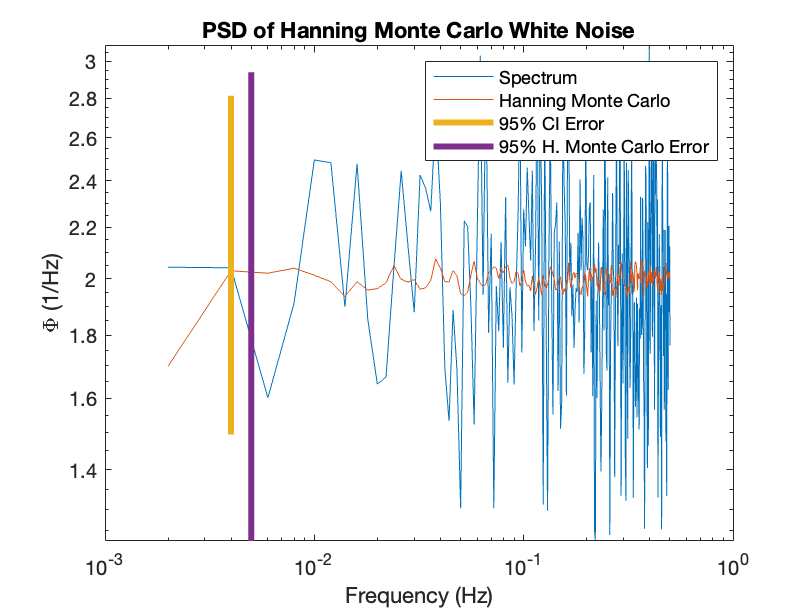


figure(112)
loglog(f,data_spectra)
hold on
loglog(f,mean(A_hann_spectra_large,2))
semilogy([0.004 0.004],[err_low err_high].*2,LineWidth=3);
semilogy([0.005 0.005],[mean(A_hann_error_low) mean(A_hann_error_high)].*1,LineWidth=3);
title('PSD of Hanning Monte Carlo White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Spectrum','Hanning Monte Carlo','95% CI Error','95% H. Monte Carlo Error')

I expected a smaller error for the Monte Carlo simulations. I'm not sure if that is an error in my calculations or a fault in my logic.

#### Problem 6

% Repeat with cosine window
t = linspace(-0.5,0.5,500); % Use period of 1 to simplify
cos_window = cos(pi*t);

% Calculate factor for overlap
cos_factor = sqrt(sum(cos_window.^2)/500);
cos_window = cos_window'*(1/cos_factor);

A_cos = A.*cos_window;

A_cos_fft = fft(A_cos);
A_cos_coef = abs(A_cos_fft(1:length(A_cos_fft)/2+1,:,:)).^2;

% Normalize
A_cos_spectra = A_cos_coef/(length(A_cos_fft)).^2; % MATLAB normalization
A_cos_spectra = A_cos_spectra*2; % Half spectra
A_cos_spectra = A_cos_spectra/df; % Units

% Combine into one large ensemble
A_cos_spectra_large = reshape(A_cos_spectra,[251,4000]);

% Plot pdf
A_hann_mu=mean(A_hann_spectra_large,1);
A_hann_sigma=std(A_hann_spectra_large);
A_hann_std=A_hann_sigma/sqrt(500);
dx=0.01;
x=1:dx:3;
[h,v]=hist(A_hann_mu,x);
h=h./sum(h)./dx;

figure(113)
plot(x,h)
ylabel('PDF')
xlabel('Sample mean')


% Sort each value at every frequency to determine error

% Average each 251x20 ensemble so we have 251 points and 200 ensembles
A_cos_spectra_average = mean(A_cos_spectra,2);
A_cos_spectra_average = reshape(A_cos_spectra_average,[251,200]);

A_cos_spectra_sorted = NaN*ones(251,200);
A_cos_error_low = NaN*ones(251,1);
A_cos_error_high = A_cos_error_low;
for idx = 1:251
    A_cos_spectra_sorted(idx,:) = sort(A_cos_spectra_average(idx,:));
    A_cos_error_low(idx) = A_cos_spectra_sorted(idx,6);
    A_cos_error_high(idx) = A_cos_spectra_sorted(idx,195);
end

mean(A_cos_error_low)/2

ans = 0.6146

mean(A_cos_error_high)/2

ans = 1.4663

mean(A_cos_error_high)/mean(A_cos_error_low)

ans = 2.3860

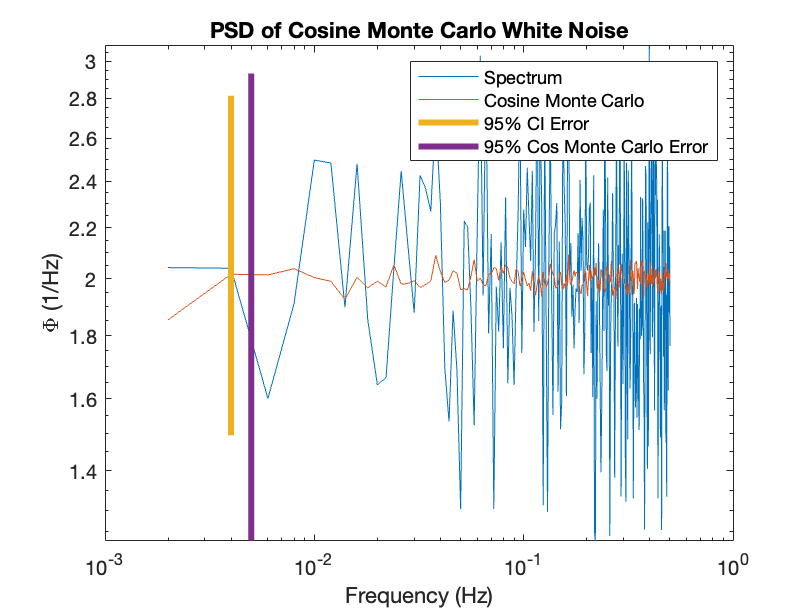


figure(114)
loglog(f,data_spectra)
hold on
loglog(f,mean(A_cos_spectra_large,2))
semilogy([0.004 0.004],[err_low err_high].*2,LineWidth=3);
semilogy([0.005 0.005],[mean(A_cos_error_low) mean(A_cos_error_high)].*1,LineWidth=3);
title('PSD of Cosine Monte Carlo White Noise')
xlabel('Frequency (Hz)')
ylabel('\Phi (1/Hz)')
legend('Spectrum','Cosine Monte Carlo','95% CI Error','95% Cos Monte Carlo Error')


% Estimating degrees of freedom by comparing to chi^2 model through good
% ol' guess and check

nu = 2*31;
A_cos_err_low = nu/chi2inv(1-.05/2,nu);
A_cos_err_high = nu/chi2inv(.05/2,nu);

mean(A_cos_error_low)/2/A_cos_err_low

ans = 0.8490

mean(A_cos_error_high)/2/A_cos_err_high

ans = 0.9963

I'm estimating about 31 degrees of freedom, which is a reduction of 8 from the fully overlapping samples.